# Chapter 7 ATAP Exercises

## Convergence for Differentiable Functions

#### Mason Mault June 2025

**Exercise 7.1: Total variation**

**Exercise 7.4: Sharpness of theorem 7.2**

Determine the total variation of $f\left(x\right)=\sin \left(100x\right)\;/\;\left(1+x^2 \right)$ on [-1, 1].

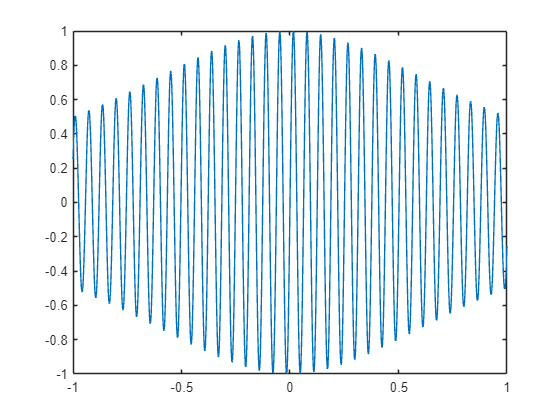

x = chebfun('x');
f = sin(100*x) / (1 + x^2);

% total variation for first derivative
tv = @(f) norm(diff(f), 1);
tv1 = tv(f);
figure
plot(f)

Which is roughly 100. The total variation of $f\left(x\right)=\sin \left(\textrm{Mx}\right)\;/\;\left(1+x^2 \right)$ on [-1, 1] is asymptotic to M as n goes to infinity. Very crudely, the reason is that $f^{\prime } \left(x\right)$ is proportional to M, so its total variation scales like M.

**Exercise 7.4: Sharpness of theorem 7.2**

Consider the three functions $f\left(x\right)=|x|,|x|^5 ,\sin \left(100x\right)$. 

Theorem 7.2 states rouhgly that if $f\left(x\right)$ and its derivatives through  $f^{\left(\nu -1\right)} \left(x\right)$are absolutely continuous on [-1,1], and the $\nu \;$th derivative is of bounded variation V, then for some $\nu \ge 1$, and any  $n>\nu \;$


$$||f-p_n ||<\frac{4V}{\pi {\nu \left(n-\nu \right)}^{\nu \;} \;\;}$$


Compute the error of the Chebyshev interpolant as a function of n for each case, and the bound on this quantity from theorem 7.2. For the first two functions, take $\nu \;$as large as possible, and for the last, take $\nu =2,4,8$.

fa = chebfun(@(x) abs(x));

fb = chebfun(@(x) abs(x).^5);
fc = chebfun(@(x) sin(100*x));

% initialization (n must be > nu or the denominator in theorem
% 7.2 is negative)
list = round(2.^linspace(3, 7, 50));
erra = zeros(length(list), 1);
errb = zeros(length(list), 1);
errc = zeros(length(list), 1);

% theoretical bound from eq 7.5
bounda = zeros(length(list), 1);
boundb = zeros(length(list), 1);
boundc2 = zeros(length(list), 1);
boundc4 = zeros(length(list), 1);
boundc8 = zeros(length(list), 1);

% total variation for nu(th) derivative of given function
% tvNu = @(f, nu) norm(diff(f, nu), 1);
tvNu = @(f, nu) sum(abs(diff(f, nu)));

% maximum number of derivatives 
nua = 1;
nub = 4;

% total variations
tvNua = tvNu(fa, nua);
tvNub = tvNu(fb, nub);
tvNuc2 = tvNu(fc, 2);
tvNuc4 = tvNu(fc, 4);
tvNuc8 = tvNu(fc, 8);

% compute chebfun interpolation and error at each value of list
for j = 1:length(list)
    n = list(j);
    x1 = chebpts(2*n);

    ga = chebfun(fa, n + 1);
    erra(j) = norm(ga(x1) - fa(x1), inf);
    bounda(j) = 4*tvNua / (pi*nua*(n - nua)^nua);

    gb = chebfun(fb, n + 1);
    errb(j) = norm(gb(x1) - fb(x1), inf);
    boundb(j) = 4*tvNub / (pi*nub*(n - nub)^nub);

    gc = chebfun(fc, n + 1);
    errc(j) = norm(gc(x1) - fc(x1), inf);
    boundc2(j) = 4*tvNuc2 / (pi*2*(n - 2)^2);
    boundc4(j) = 4*tvNuc4 / (pi*4*(n - 4)^4);
    boundc8(j) = 4*tvNuc8 / (pi*8*(n - 8)^8);
end

Plot the errors for each function, noticing the theoretical bound is always above the actual curve.

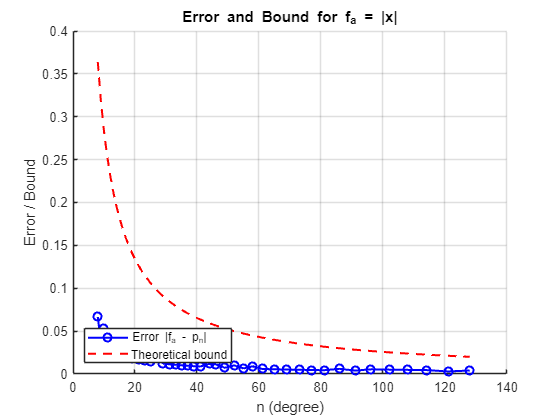

figure
hold on
semilogy(list, erra, 'b-o', 'LineWidth', 1.5, 'DisplayName', 'Error |f_a - p_n|')
semilogy(list, bounda, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Theoretical bound')
xlabel('n (degree)')
ylabel('Error / Bound')
title('Error and Bound for f_a = |x|')
legend('Location', 'southwest')
grid on
hold off

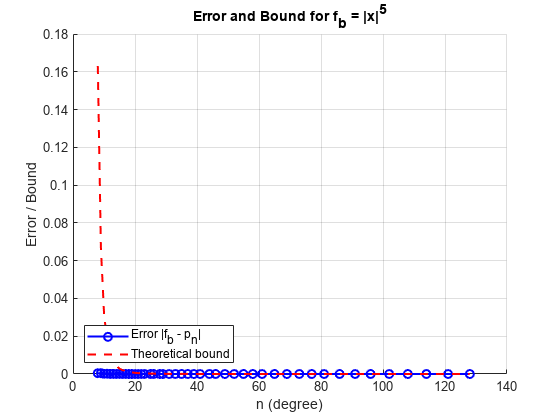


figure
hold on
semilogy(list, errb, 'b-o', 'LineWidth', 1.5, 'DisplayName', 'Error |f_b - p_n|')
semilogy(list, boundb, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Theoretical bound')
xlabel('n (degree)')
ylabel('Error / Bound')
title('Error and Bound for f_b = |x|^5')
legend('Location', 'southwest')
grid on
hold off

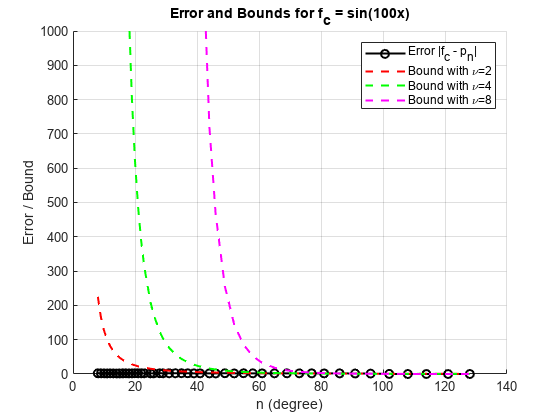


figure
hold on
semilogy(list, errc, 'k-o', 'LineWidth', 1.5, 'DisplayName', 'Error |f_c - p_n|')
semilogy(list, boundc2, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Bound with \nu=2')
semilogy(list, boundc4, 'g--', 'LineWidth', 1.5, 'DisplayName', 'Bound with \nu=4')
semilogy(list, boundc8, 'm--', 'LineWidth', 1.5, 'DisplayName', 'Bound with \nu=8')
xlabel('n (degree)')
ylabel('Error / Bound')
title('Error and Bounds for f_c = sin(100x)')
legend('Location', 'northeast')
grid on
hold off
ylim([0,1000])